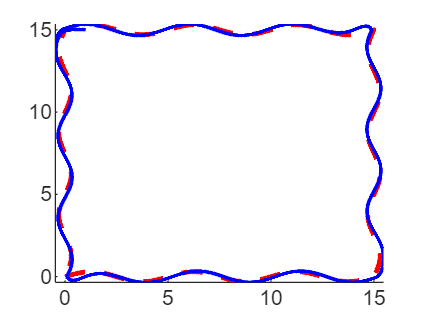

clc; clear; close all;

%% 1. Robot Parameters
% -------------------------------
R = 0.1;        % Wheel radius [m]
L = 0.5;        % Distance between wheels [m]
robot_length = 0.4; % Robot body length
robot_width = 0.3;  % Robot body width

% Simulation parameters
T = 800;         % Total simulation time [s]
dt = 0.1;       % Time step [s]
t = 0:dt:T;     % Time vector

%% 2. Path Definition (Sinusoidal Square)
% -------------------------------

side = 15;          % length of each side
step = 0.02;       % resolution
amp  = 0.3;        % amplitude of waves
freq = 6*pi/side;  % frequency so exactly one wave fits each side

%% Bottom (left → right)
x1 = 0:step:side;
y1 = amp * sin(freq * x1);

%% Right side (bottom → top)
y2 = 0:step:side;
x2 = side + amp * sin(freq * y2);

%% Top side (right → left)
x3 = side:-step:0;
y3 = side + amp * sin(freq * x3);

%% Left side (top → bottom)
y4 = side:-step:0;
x4 = amp * sin(freq * y4);

%% Combine into full path
x_path = [x1, x2, x3, x4];
y_path = [y1, y2, y3, y4];

path = [x_path' y_path'];

%% 3. Initialization
% -------------------------------
state = [1, 15, 3]; % [x, y, theta]
states = zeros(length(t), 3);
states(1,:) = state;
errors = zeros(length(t), 2); % [distance_error, angle_error]

%% 4. Main Simulation Loop
% -------------------------------
for i = 2:length(t)
    % Calculate errors
    [dist_err, ang_err] = calculate_errors(state, path, robot_length);
    errors(i, :) = [dist_err, ang_err];
    
    % Apply control function
    [omega_r, omega_l] = control_function(errors,i);
    
    % Update kinematics
    v_r = R * omega_r;
    v_l = R * omega_l;
    
    v = (v_r + v_l)/2;
    w = (v_r - v_l)/L;
    
    state(3) = state(3) + w*dt;
    state(1) = state(1) + v*cos(state(3))*dt;
    state(2) = state(2) + v*sin(state(3))*dt;
    
    states(i,:) = state;
end

%% 5. Visualization
% -------------------------------
figure;
hold on;
plot(path(:,1), path(:,2), 'r--', 'LineWidth', 2)
plot(states(:,1), states(:,2), 'b', 'LineWidth', 1.5)

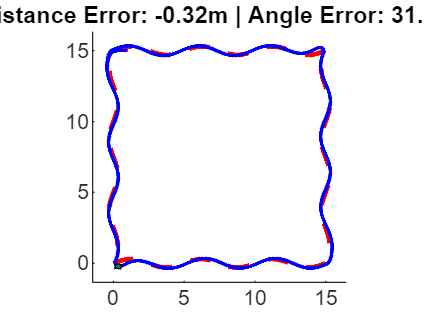


% Animation
margin = 1;
for i = 1:10:length(t)
    clf;

    xlim([-1.0 13.5])
    ylim([-1.0 6.0])
    hold on;

    plot(path(:,1), path(:,2), 'r--', 'LineWidth', 2)
    plot(states(:,1), states(:,2), 'b', 'LineWidth', 1.5)

    theta = states(i,3);
    x = states(i,1);
    y = states(i,2);

    body = [-robot_length/2 -robot_width/2;
            robot_length/2 -robot_width/2;
            robot_length/2  robot_width/2;
           -robot_length/2  robot_width/2];
    R_matrix = [cos(theta) -sin(theta);
                sin(theta)  cos(theta)];
    rotated_body = (R_matrix * body')' + [x, y];
    fill(rotated_body(:,1), rotated_body(:,2), 'g', 'FaceAlpha', 0.5)

    wheel_pos = [-robot_length/2  robot_width/2;
                -robot_length/2 -robot_width/2];
    for j = 1:2
        wheel_center = (R_matrix * wheel_pos(j,:)')' + [x, y];
        rectangle('Position', [wheel_center(1)-0.05, wheel_center(2)-0.05, 0.1, 0.1],...
                  'Curvature', [1 1], 'FaceColor', 'k')
    end

    x_min = min([path(:,1); states(1:i,1)]) - margin;
    x_max = max([path(:,1); states(1:i,1)]) + margin;
    y_min = min([path(:,2); states(1:i,2)]) - margin;
    y_max = max([path(:,2); states(1:i,2)]) + margin;

    axis equal;
    xlim([x_min, x_max])
    ylim([y_min, y_max])

    title(sprintf('Distance Error: %.2fm | Angle Error: %.2f°', errors(i,1), errors(i,2)))

    pause(0.05);
    drawnow;
end

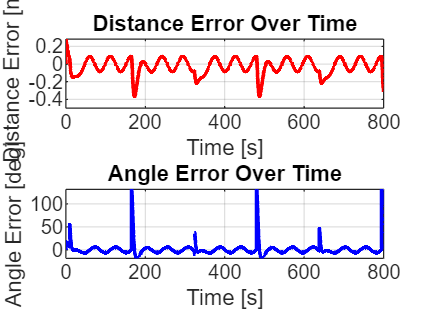


plot_errors(errors,t);


%% 6. Functions
% -------------------------------

function [distance_error, angle_error] = calculate_errors(state, path, robot_length)
    dx = path(:,1) - state(1);
    dy = path(:,2) - state(2);
    distances = sqrt(dx.^2 + dy.^2);
    [~, idx] = min(distances);

    distance_error = distances(idx);

    if idx > 1 && idx < size(path, 1)
        dy = path(idx+1,2) - path(idx-1,2);
        dx = path(idx+1,1) - path(idx-1,1);
    elseif idx == 1
        dy = path(idx+1,2) - path(idx,2);
        dx = path(idx+1,1) - path(idx,1);
    else
        dy = path(idx,2) - path(idx-1,2);
        dx = path(idx,1) - path(idx-1,1);
    end

    theta_path = atan2(dy, dx);
    angle_error = theta_path - state(3);
    angle_error = atan2(sin(angle_error), cos(angle_error)) * (180 / pi);

    cross_product = (dx * (state(2) - path(idx,2))) - (dy * (state(1) - path(idx,1)));
    if cross_product > 0
        distance_error = abs(distance_error);
    else
        distance_error = -abs(distance_error);
    end
end

function [omega_r, omega_l] = control_function(errors, i)
    kp = 0.4;
    ki = 0.1;
    kd = 100;
    d = 0;
    sum = 0;
    ns = 5;

    if i > 2
        d = errors(i,1) - errors(i-1,1);
    else
        d = 0;
    end

    if i < ns
        for j = 1:i-1
            sum = sum + errors(i-j,1);
        end
    else
        for j = 1:ns-1
            sum = sum + errors(i-j,1);
        end   
    end

    w = kp * errors(i,1) + kd * d + ki * sum;

    % Limit rotation speed
    if w > 2
        w = 2;
    end
    if w < -2
        w = -2;
    end

    angle_error = errors(i,2);

    if errors(i,1) > 0.5 && errors(i,2) > 70 && errors(i,2) < 90
        omega_r = 1;
        omega_l = 1;
    elseif errors(i,1) < -0.5 && errors(i,2) < -70 && errors(i,2) > -90
        omega_r = 1;
        omega_l = 1;
    else
        omega_r = 1-w;
        omega_l = 1+w;
    end
end

function plot_errors(errors, t)
    figure;

    subplot(2,1,1);
    plot(t, errors(:,1), 'r', 'LineWidth', 1.5);
    xlabel('Time [s]');
    ylabel('Distance Error [m]');
    title('Distance Error Over Time');
    grid on;

    subplot(2,1,2);
    plot(t, errors(:,2), 'b', 'LineWidth', 1.5);
    xlabel('Time [s]');
    ylabel('Angle Error [deg]');
    title('Angle Error Over Time');
    grid on;
end


